# Opulent Voice Numerology Study

Abraxas3d

July 2022

## Original Quadratic Permutation Polynomial From M17 Protocol

f(x) = 45x^2 + 92x with length 368

Treating this as Z/368Z

we need a new f(x) for Opulent Voice frame length of 1480

x = (0:367)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


permutation = mod(45*x + 92.*x.*x, 368)

permutation =      0   137    90   227   180   317   270    39   360   129    82   219   172   309   262    31   352   121    74   211   164   301   254    23   344   113    66   203   156   293   246    15   336   105    58   195   148   285   238     7   328    97    50   187   140   277   230   367   320    89



permutation_reversed = mod(45*permutation + 92.*permutation.*permutation, 368)

permutation_reversed =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49





if length(permutation) == length(unique(permutation))
    disp('There are no repeats in original vector')
    
end

There are no repeats in original vector




for j = 1:367
    original_distance(j) = abs(permutation(j) - permutation(j+1));
end
    disp('Minimum distance is:')

Minimum distance is:


    min(original_distance)

ans = 47

    disp('This is')

This is


    (min(original_distance)/368)*0.04

ans = 0.0051

    disp('milliseconds.')

milliseconds.


## New Quadratic Permutation Polynomial for Opulent Voice

Maximum spread quadratic permutation polynomial example. 

k = (6)

k = 6


linear_term = 2.^k - 1

linear_term = 63

quadratic_term = 2.^(k+1)

quadratic_term = 128

modulo = 2.^(2.*k -1)

modulo = 2048


max_spread = mod(linear_term*x + quadratic_term.*x.*x, modulo)

max_spread =            0         191         638        1341         252        1467         890         569         504         695        1142        1845         756        1971        1394        1073        1008        1199        1646         301        1260         427        1898        1577        1512        1703         102         805        1764         931         354          33        2016         159         606        1309         220        1435         858         537         472         663        1110        1813         724        1939        1362        1041         976        1167




if length(max_spread) == length(unique(max_spread))
    disp('There are no repeats in permutated vector')
    
end

There are no repeats in permutated vector


## Determine new coefficients for frame length of 1480

368/4

ans = 92

1480/4

ans = 370


92/2

ans = 46

370/2

ans = 185


opv_index = (0:1479) %index of bit locations for a frame

opv_index =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


opv_data = randperm(1480,1480) %data we want to use.

opv_data =         1474        1025        1408        1451        1189        1241        1075         929        1116        1367        1303         112        1411         408        1410        1366        1028        1037        1346         194         671        1416        1388         821         455         628        1477        1301         792         734          73         992         406         470         337        1127         346        1291         705        1381        1251         598         706        1007        1154        1095         139         279         419         935


%returns a row vector containing k unique integers
%selected randomly from 1 to n.


opv_permutation = mod(177*opv_index + 370.*opv_index.*opv_index, 1480) %experimentally determined the linear term

opv_permutation =            0         547         354         901         708        1255        1062         129        1416         483         290         837         644        1191         998          65        1352         419         226         773         580        1127         934           1        1288         355         162         709         516        1063         870        1417        1224         291          98         645         452         999         806        1353        1160         227          34         581         388         935         742        1289        1096         163



%test for simple inverse
%opv_permutation_inversed = mod(177*opv_permutation + 370.*opv_permutation.*opv_permutation, 1480)

%reverse using opv_permutation

opv_permutation_reversed_i = [opv_permutation; opv_index] 

opv_permutation_reversed_i =            0         547         354         901         708        1255        1062         129        1416         483         290         837         644        1191         998          65        1352         419         226         773         580        1127         934           1        1288         355         162         709         516        1063         870        1417        1224         291          98         645         452         999         806        1353        1160         227          34         581         388         935         742        1289        1096         163
           0           1           2           3           4           5           6           7           8           9          10          11          12          13          14          15          16          17          18          19          20          21          22          23          24          25          26          27          28          29          


deinterleaver_key = sortrows(opv_permutation_reversed_i',1)'

deinterleaver_key =            0           1           2           3           4           5           6           7           8           9          10          11          12          13          14          15          16          17          18          19          20          21          22          23          24          25          26          27          28          29          30          31          32          33          34          35          36          37          38          39          40          41          42          43          44          45          46          47          48          49
           0          23         786         809          92         115         878         901         184         207         970         993         276         299        1062        1085         368         391        1154        1177         460         483        1246        1269         552         575        1338        1361         644         667        1430       



check_result = zeros([1 1480])

check_result =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for m = 2:1480
    %deinterleaver_key(2,m)
    
    check_result(m) = opv_permutation_reversed_i(1,((deinterleaver_key(2,m))+1));
end

if check_result == opv_index
    disp('check result passed')
end

check result passed



%test for complete coverage
if length(opv_permutation) == length(unique(opv_permutation))
    disp('There are no repeats in opv_permutation vector')
else
    disp('Problem with this one')
    errors = unique(opv_permutation)
    
end

There are no repeats in opv_permutation vector




%test for minimum distance between adjacent bits
for i = 1:1479
    distance(i) = abs(opv_permutation(i) - opv_permutation(i+1));
end
    disp('Adjacent bits have a ')

Adjacent bits have a 


    minimum_distance = min(distance)

minimum_distance = 193

    disp('This resuls in a')

This resuls in a


    minimum_time = (min(distance)/1480)*0.04

minimum_time = 0.0052

    disp('milliseconds.')

milliseconds.


    disp('This is ')

This is 


    minimum_time*1000

ans = 5.2162

    disp("microseconds.")

microseconds.


    
    
    
%test for maximum distance between adjacent bits
for i = 1:1479
    distance(i) = abs(opv_permutation(i) - opv_permutation(i+1));
end
    disp('Adjacent bits have a ')

Adjacent bits have a 


    maximum_distance = max(distance)

maximum_distance = 1287

## Randomizer Table

Select 185 random numbers (1 to 255) from a uniform distribution. 

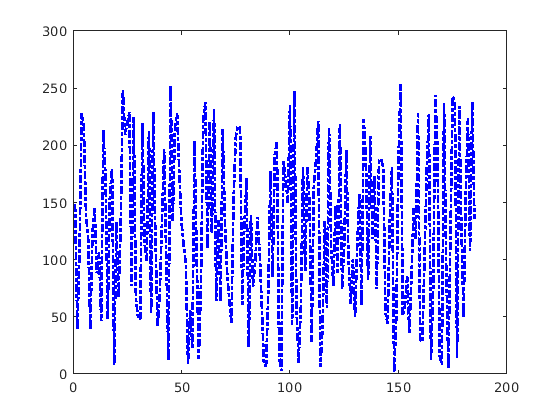

pd = makedist('Uniform'); % Uniform distribution
pd_array = random(pd,1480/8,1);
r = ceil(255.*pd_array);
r_hex = dec2hex(r);


x = 1:1480/8;

figure
plot(x,r,'b-.','LineWidth',2)

## Selected Randomizer Digits in Hexadecimal

 'A3'    '81'    '5C'    'C4'    'C9'    '08'    '0E'    '53'    'CC'    'A1'    'FB'    '29'    '9E'    '4F'    '16'    'E0'    '97'    '4E'    '2B'    '57'    '12'    'A7'    '3F'    'C2'    '4D'    '6B'    '0F'    '08'    '30'    '46'    '11'    '56'    '0D'    '1A'    '13'    'E7'    '50'    '97'    '61'    'F3'    'BE'    'E3'    '99'    'B0'    '64'    '39'    '22'    '2C'    'F0'    '09'    'E1'    '86'    'CF'    '73'    '59'    'C2'    '5C'    '8E'    'E3'    'D7'    '3F'    '70'    'D4'    '27'    'C2'    'E0'    '81'    '92'    'DA'    'FC'    'CA'    '5A'    '80'    '42'    '83'    '15'    '0F'    'A2'    '9E'    '15'    '9C'    '8B'    'DB'    'A4'    '46'    '1C'    '10'    '9F'    'B3'    '47'    '6C'    '5E'    '15'    '12'    '1F'    'AD'    '38'    '3D'    '03'    'BA'    '90'    '8D'    'BE'    'D3'    '65'    '23'    '32'    'B8'    'AB'    '10'    '62'    '7E'    'C6'    '26'    '7C'    '13'    'C9'    '65'    '3D'    '15'    '15'    'ED'    '35'    'F4'    '57'    'F5'    '58'    '11'    '9D'    '8E'    'E8'    '34'    'C9'    '59'    'F8'    'D6'    'B6'    '37'    '04'    '36'    '89'    '1C'    'DA'    'E9'    '56'    '78'    '01'    '50'    '7C'    '43'    'AF'    'E9'    '92'    '44'    'ED'    '11'    'A0'    'F2'    '84'    'F4'    '46'    '87'    'E9'    '37'    'D3'    '24'    '70'    'E0'    'B4'    '7F'    '9C'    '14'    '3E'    '07'    'D8'    '04'    '8D'    '1F'    '96'    '9F'    'BF'   '50'    'EA'    'C8'    '1A'

## Selected Randomizer Digits in Decimal Format

163 129 92 196 201 8 14 83 204 161 251 41 158 79 22 224 151 78 43 87 18 167 63 194 77 107 15 8 48 70 17 86 13 26 19 231 80 151 97 243 190 227 153 176 100 57 34 44 240 9 225 134 207 115 89 194 92 142 227 215 63 112 212 39 194 224 129 146 218 252 202 90 128 66 131 21 15 162 158 21 156 139 219 164 70 28 16 159 179 71 108 94 21 18 31 173 56 61 3 186 144 141 190 211 101 35 50 184 171 16 98 126 198 38 124 19 201 101 61 21 21 237 53 244 87 245 88 17 157 142 232 52 201 89 248 214 182 55 4 54 137 28 218 233 86 120 1 80 124 67 175 233 146 68 237 17 160 242 132 244 70 135 233 55 211 36 112 224 180 127 156 20 62 7 216 4 141 31 150 159 191 80 234 200 26

## Sample Filter and FreqDevEstimator

What do these IIR filters look like? 

[h,w] = freqz([4.24433681e-5, 8.48867363e-5, 4.24433681e-5], [1, -1.98148851, 0.98165828],1024);
figure(10)
plot(w/pi,20*log10(abs(h)))

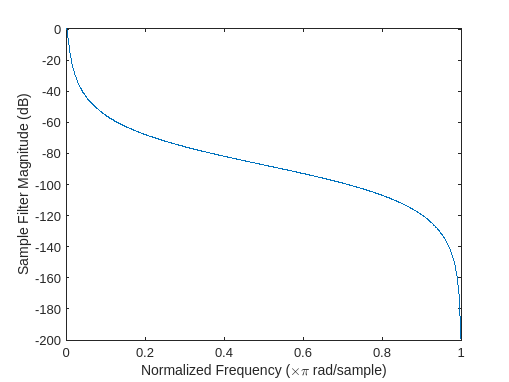


xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Sample Filter Magnitude (dB)')

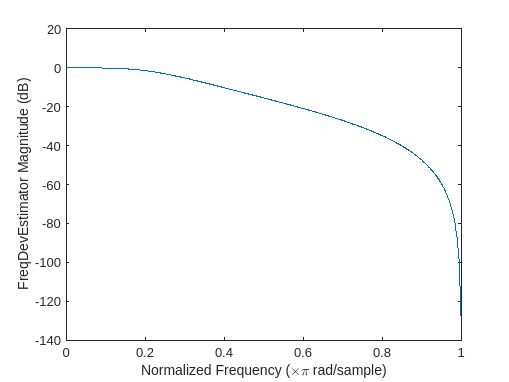



[h2, w2] = freqz([0.09763107, 0.19526215, 0.09763107],[1, -0.94280904, 0.33333333], 1024);
figure(11)
plot(w2/pi,20*log10(abs(h2)))

xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('FreqDevEstimator Magnitude (dB)')

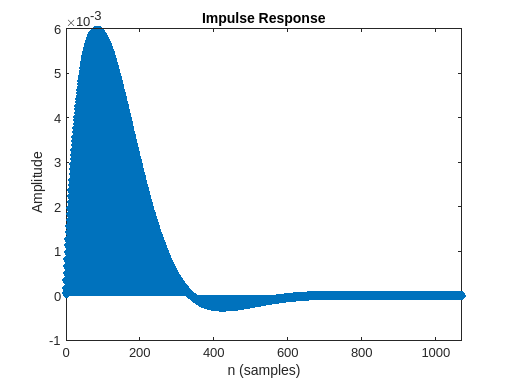



%Sample Filter
impz([4.24433681e-5, 8.48867363e-5, 4.24433681e-5], [1, -1.98148851, 0.98165828])

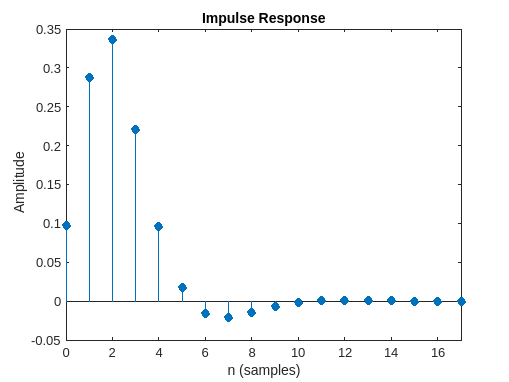


%FreqDevEstimator
impz([0.09763107, 0.19526215, 0.09763107],[1, -0.94280904, 0.33333333])

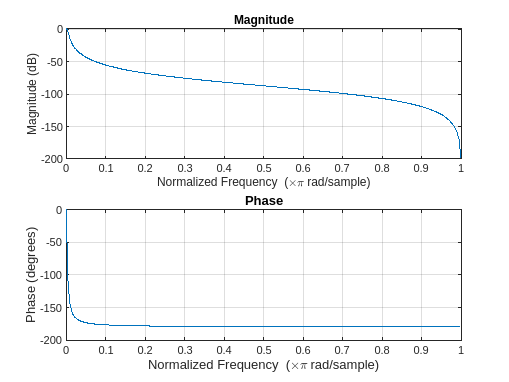


%Sample Filter
freqz([4.24433681e-5, 8.48867363e-5, 4.24433681e-5], [1, -1.98148851, 0.98165828],1024);

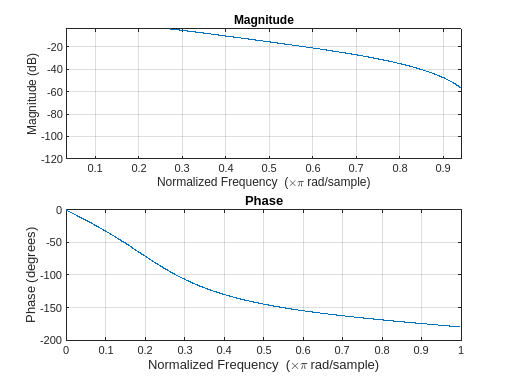


%FreqDevEstimator
freqz([0.09763107, 0.19526215, 0.09763107],[1, -0.94280904, 0.33333333], 1024);

% This is created with sample rate of 25 and a cut off of 25/8
% This is an 8 frame filter (320mS in previous code). 

What does 1/240 and 1/4 Nyquist rate mean? 

Well, what is the Nyquist rate of the original codebase?

Nyquist is twice the bandwidth of the sampled signal. 

fs = 4800

fs = 4800

NyquistRate = 2*fs

NyquistRate = 9600

SampleFilterRate = NyquistRate/240

SampleFilterRate = 40

FreqDevEstimatorRate = NyquistRate/4

FreqDevEstimatorRate = 2400

## Deviation Calculations

clear all
clf
symbol_rate = 18700;
symbol_period = 1/symbol_rate

symbol_period = 5.3476e-05

deviation = 0.5*symbol_rate

deviation = 9350

%carrier_frequency = 905.05e6
carrier_frequency = 15000

carrier_frequency = 15000

ans = 66000


outer_deviation = 0.25 * symbol_rate * 3

outer_deviation = 14025


inner_deviation = 0.25 * symbol_rate

inner_deviation = 4675


modulation_index = 2*outer_deviation * symbol_period/3

modulation_index = 0.5000




%XXXXXXXXXXXXXXXXXXXXXXX Binary-FSK modulation XXXXXXXXXXXXXXXXXXXXXXXXXXX%


f1 = carrier_frequency - outer_deviation;   % carrier frequency for information as 11
f2 = carrier_frequency - inner_deviation;   % carrier frequency for information as 10
f3 = carrier_frequency + inner_deviation;   % carrier frequency for information as 00
f4 = carrier_frequency + outer_deviation;   % carrier frequency for information as 01


Am = 1;
number_symbols = 10

number_symbols = 10

%samples_per_symbol = 2*carrier_frequency
samples_per_symbol = 20

samples_per_symbol = 20

t = 0:symbol_period/samples_per_symbol:number_symbols*symbol_period;
time = [1:1:size(t,[2])]

time =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



%data = [11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01 11 01]
data = [00 01 11 10 00 01 11 10 00 01 11 10 00 01 11 10 00 01 11 10 00 01 11 10 00 01 11 10 11 00]

data =      0     1    11    10     0     1    11    10     0     1    11    10     0     1    11    10     0     1    11    10     0     1    11    10     0     1    11    10    11     0


modulated_signal = []


modulated_signal =

     []



%data_index = [1:1:size(data,[2])]

offset = f1;
data_index = 1

data_index = 1


for t_index =[1:1:size(t,[2])]
    modulated_signal(t_index) = Am*cos(2*pi*(offset)*t(t_index));
    if mod(t_index,samples_per_symbol) == 0
        if data(data_index) == 0
            offset = f3
        elseif data(data_index) == 1
            offset = f4
        elseif data(data_index) == 11 
            offset = f1
        else
            offset = f2
        end
        data_index = data_index + 1
    end
end

offset = 19675

data_index = 2

offset = 29025

data_index = 3

offset = 975

data_index = 4

offset = 10325

data_index = 5

offset = 19675

data_index = 6

offset = 29025

data_index = 7

offset = 975

data_index = 8

offset = 10325

data_index = 9

offset = 19675

data_index = 10

offset = 29025

data_index = 11

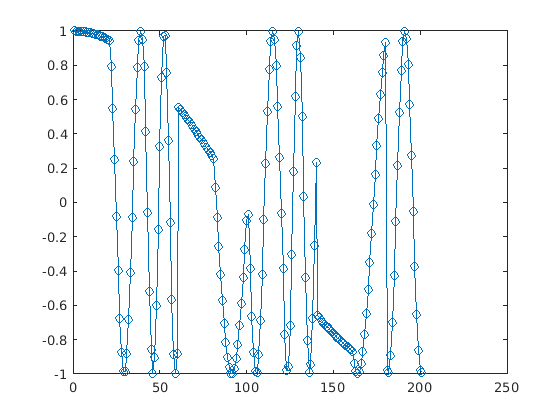


figure(12)
plot(time,modulated_signal,'-o')